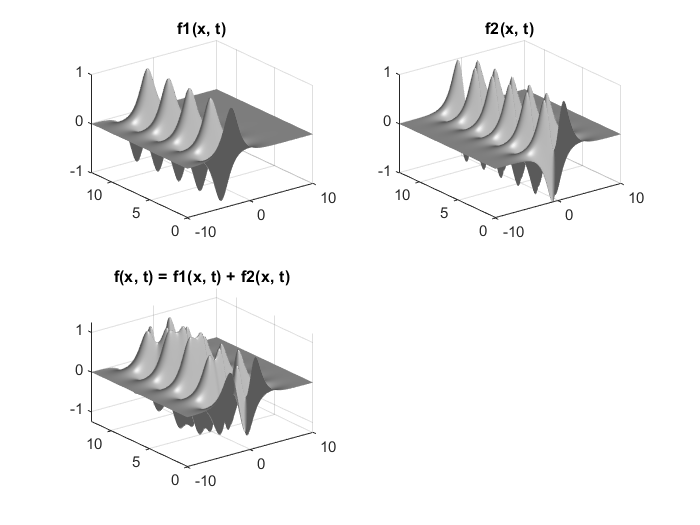

clear all;
close all;
clc;

% Generate meshgrid 
xi = linspace(-10, 10, 400);
t = linspace(0, 4*pi, 200);
dt = t(2) - t(1);

[xgrid, tgrid] = meshgrid(xi, t);

% Create two spatio-temporal signals
f1 = sech(xgrid + 3) .* (1*exp(1i*2.3*tgrid));
f2 = (sech(xgrid).*tanh(xgrid)).*(2*exp(1i*2.8*tgrid));

f = f1 + f2;

% SVD for sum of functions
[u, s, v] = svd(f.');

% Plotting the 3 signals
figure(1);
subplot(2,2,1); surfl(xgrid, tgrid, real(f1));  shading interp; colormap gray;  title('f1(x, t)');
subplot(2,2,2); surfl(xgrid, tgrid, real(f2));  shading interp; colormap gray;  title('f2(x, t)');
subplot(2,2,3); surfl(xgrid, tgrid, real(f));  shading interp; colormap gray; title('f(x, t) = f1(x, t) + f2(x, t)');

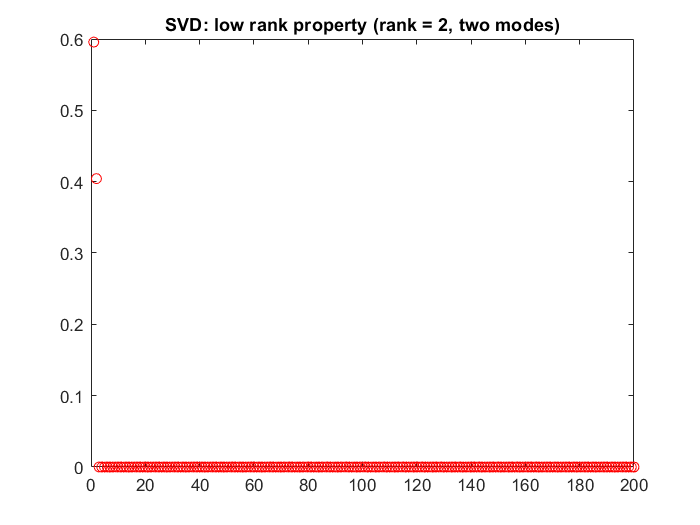

figure(2);
plot(diag(s) / sum(diag(s)), 'ro'); title('SVD: low rank property (rank = 2, two modes)');

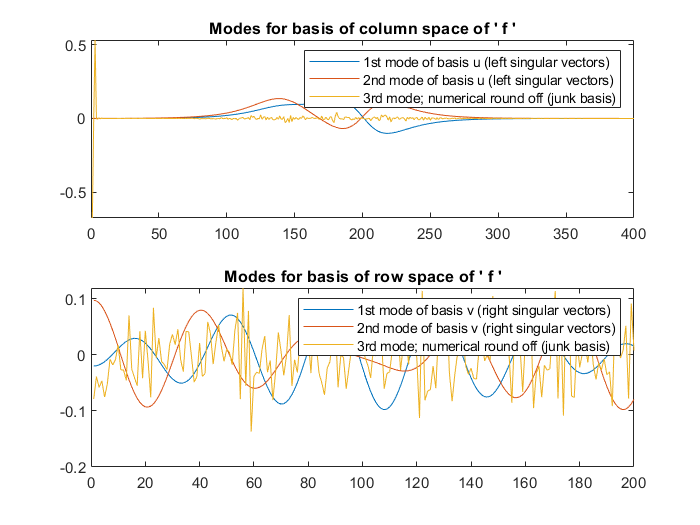

% Analysing the modes for the two signals

figure(3);
subplot(2,1,1); plot(real(u(:, 1:3))); 
legend('1st mode of basis u (left singular vectors)', ...
        '2nd mode of basis u (left singular vectors)', ...
        '3rd mode; numerical round off (junk basis)  '); 
title('Modes for basis of column space of '' f ''');

subplot(2,1,2); plot(real(v(:, 1:3)));
legend('1st mode of basis v (right singular vectors)', ...
        '2nd mode of basis v (right singular vectors)', ...
        '3rd mode; numerical round off (junk basis)  '); 
title('Modes for basis of row space of '' f ''');

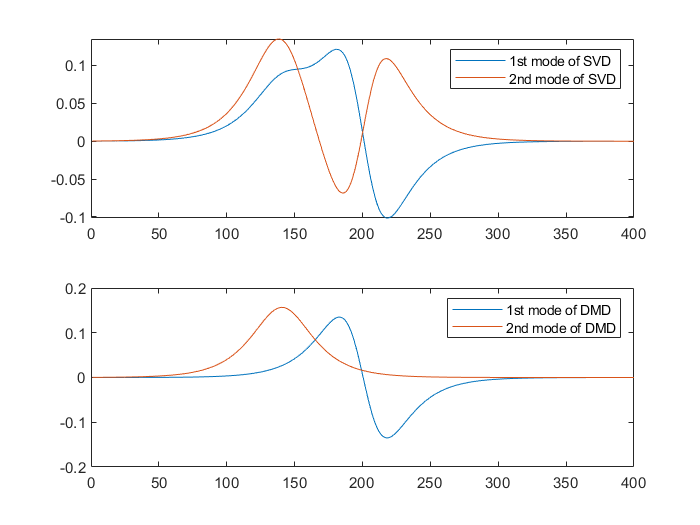

% Dynamic Mode Decomposition (DMD)
X = f.';    %Lies in C^(spatio, temporal)

X1 = X(:, 1:end-1);
X2 = X(:, 2:end);

% STEP 1: singular value decomposition (SVD)
r = 2;      % rank-r truncation
[U, S, V] = svd(X1, 'econ');

Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% STEP 2: low-rank subspace matrix 
Atilde = Ur'*X2*Vr*Sr^(-1);

% STEP 3: eigen decomposition
[W, D] = eig(Atilde);

%% STEP 4: real space DMD mode
Phi = X2*Vr*Sr^(-1)*W;   % DMD modes

lamdba = diag(D);       % eigen value
omega = log(lamdba)/dt; % log of eigen value

% Visulising modes obtained by DMD
figure(4); 
subplot(2,1,1); plot(real(u(:, 1:2)));
legend('1st mode of SVD', ...
        '2nd mode of SVD'); 
subplot(2,1,2); plot(real(Phi));
legend('1st mode of DMD', ...
        '2nd mode of DMD'); 

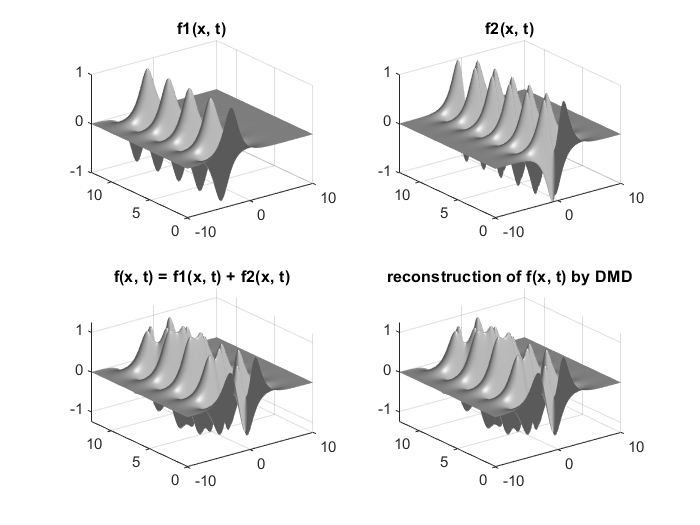

% STEP 5: reconstruct the signal
x1 = X(:, 1);       % X at time t = 0
b = pinv(Phi)*x1;   % initial value; \: pseudo inverse

t_dyn = zeros(r, length(t));

for i = 1:length(t)
   t_dyn(:, i) = (b.*exp(omega*t(i))); 
end

f_dmd = Phi*t_dyn;

figure(1);
subplot(2,2,1); surfl(xgrid, tgrid, real(f1));  shading interp; colormap gray;  title('f1(x, t)');
subplot(2,2,2); surfl(xgrid, tgrid, real(f2));  shading interp; colormap gray;  title('f2(x, t)');
subplot(2,2,3); surfl(xgrid, tgrid, real(f));  shading interp; colormap gray; title('f(x, t) = f1(x, t) + f2(x, t)');
subplot(2,2,4); surfl(xgrid, tgrid, real(f_dmd).');  shading interp; colormap gray; title('reconstruction of f(x, t) by DMD');

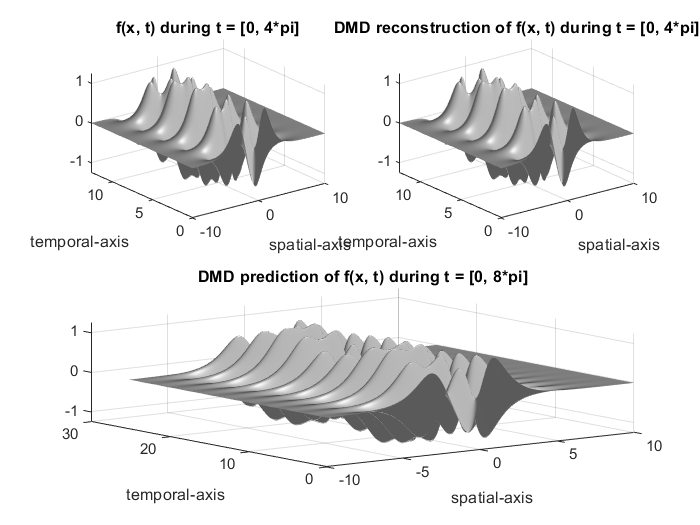

% Predict furture state using DMD

% Time upto which we need prediction
t_ext = linspace(0, 8*pi, 400);

[xgrid_ext, tgrid_ext] = meshgrid(xi, t_ext);

t_ext_dyn = zeros(r, length(t_ext));

for i = 1:length(t_ext)
   t_ext_dyn(:, i) = (b.*exp(omega*t_ext(i))); 
end

f_dmd_ext = Phi*t_ext_dyn;

figure(4);
subplot(2,2,1); surfl(xgrid, tgrid, real(f));  shading interp; colormap gray; 
xlabel('spatial-axis'); ylabel('temporal-axis'); title('f(x, t) during t = [0, 4*pi]');
subplot(2,2,2); surfl(xgrid, tgrid, real(f_dmd).');  shading interp; colormap gray; 
xlabel('spatial-axis'); ylabel('temporal-axis'); title('DMD reconstruction of f(x, t) during t = [0, 4*pi]');
subplot(2,2,[3,4]); surfl(xgrid_ext, tgrid_ext, real(f_dmd_ext).');  shading interp; colormap gray; 
xlabel('spatial-axis'); ylabel('temporal-axis'); title('DMD prediction of f(x, t) during t = [0, 8*pi]');

% If eigen value: lambda or omega has tiny real part > 0,
% the output of system function which is spanned 
% by eigen vectors with eigen values goes to the infinity.
% It is one of the limitation of DMD method.

format long e;
disp(omega);    % eigen values exist on the imaginary part.

      5.549129213779098e-15 + 2.799999999999998e+00i
     -7.774275086631117e-15 + 2.299999999999999e+00i



disp('real part: numerical round off');

real part: numerical round off


disp('imag part: eigen values');

imag part: eigen values
